# **Experiment 2-**

# **Frequency Modulation**

## **Kushagra Khatwani**

### **190020021**

#### Initial Variables-                                                                                                                  

clear all;
close all;

fs = 10000;                                  %Sampling frequency 
fc = 200;                                    %Carrier frequency
kf = 1;                                      %frequency Deviation
Ac = 3;                                      %Carrier Amplitude

#### Message SIgnal-

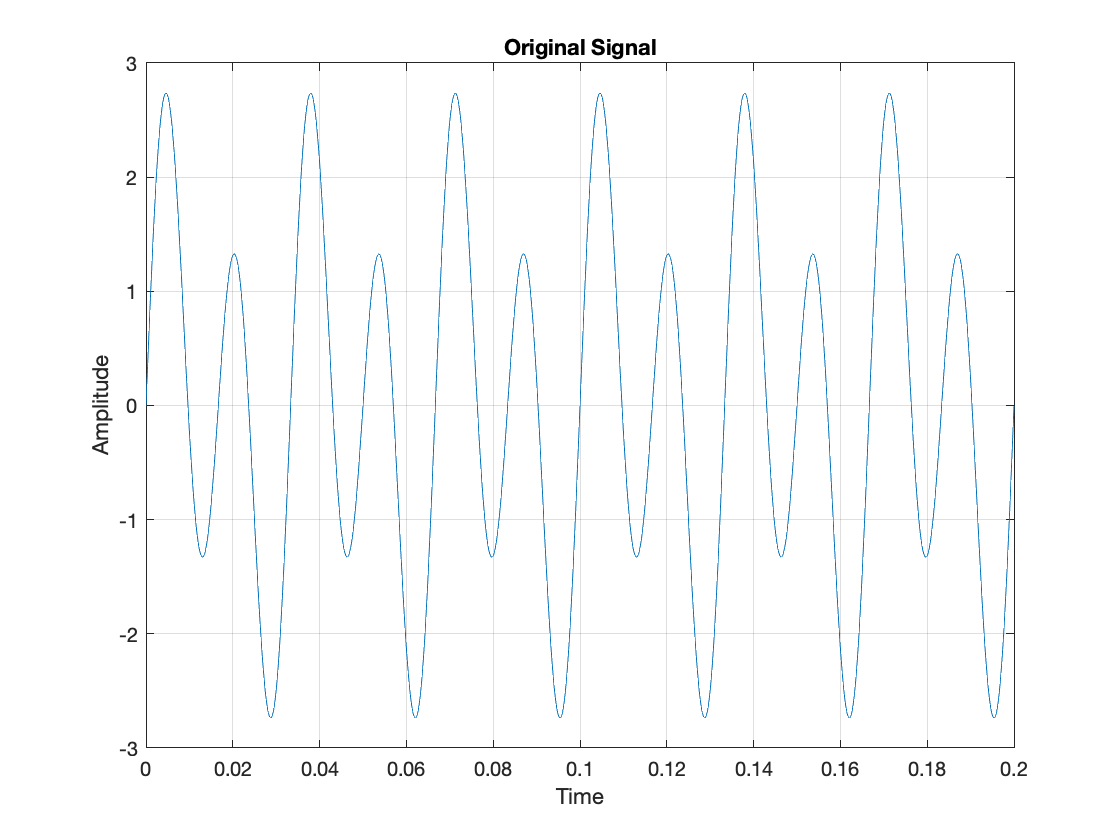

t1 = [0:1/fs:0.2];   
%Message Signal
msg = sin(2*pi*30*t1)+2*sin(2*pi*60*t1);  


%Taking Fourier Transform of original signal-
n = length(msg);
Y = fft(msg);
Fmsg = fftshift(Y);
fshift = (-n/2:n/2-1)*(fs/n);              % zero-centered frequency range
freq = abs(Fmsg);  

%Plotting Original signal-
plot(t1, msg); 
title('Original Signal'); 
xlabel('Time'); 
ylabel('Amplitude'); 
grid on;

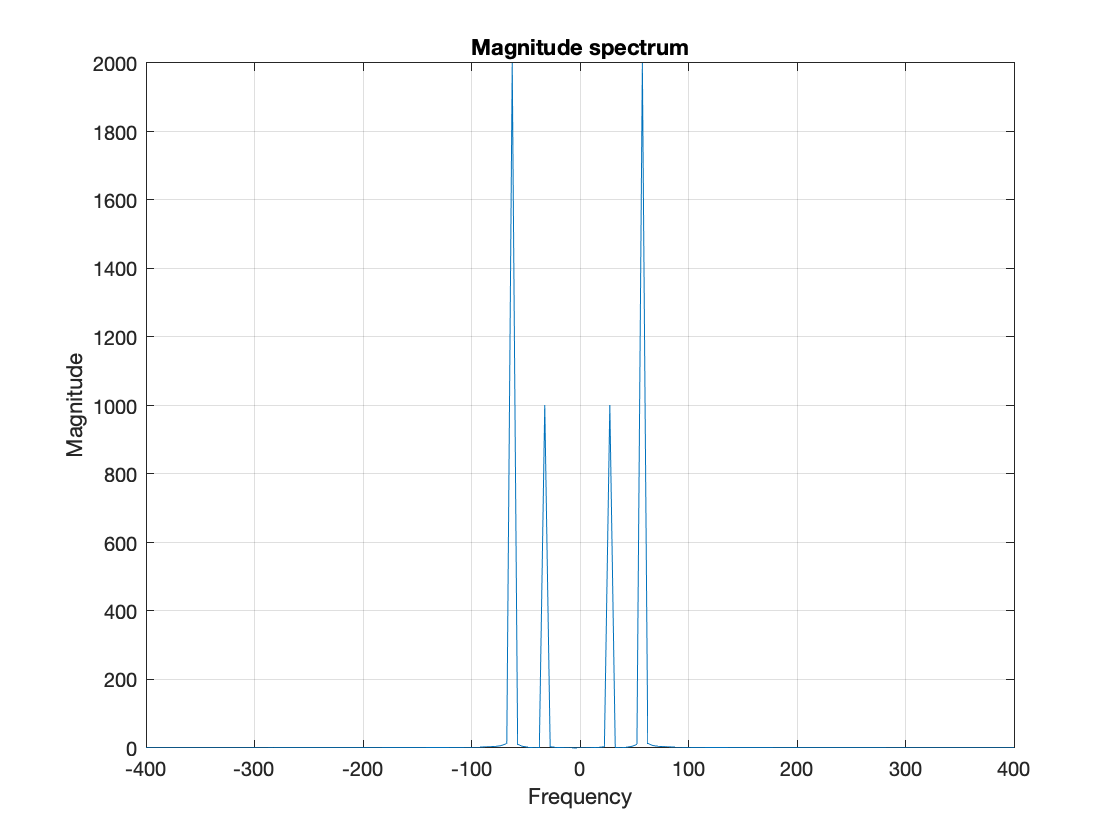

%Plotting Magnitude Spectrum of Original signal-
plot(fshift, freq); 
title('Magnitude spectrum'); 
xlim([-2*fc,2*fc]);
xlabel('Frequency'); 
ylabel('Magnitude'); 
grid on;

#### Modulation of FM signal-

If our message signal is m(t) then-


$$\theta(t) = \theta(0) +2\pi k_{f} \int_{0}^{t}m(\tau)d\tau$$


So our modulated signal-


$$u(t) = Ac\times cos(2\pi f_{c}t + \theta(t))$$


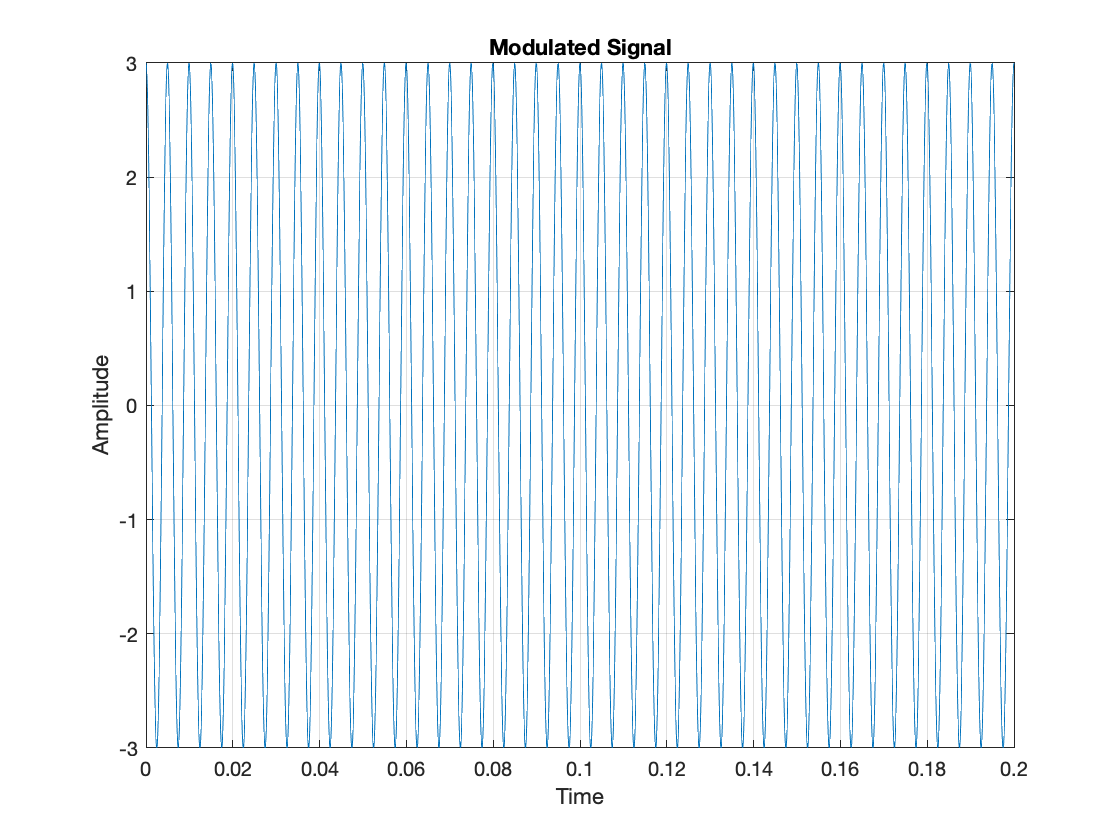

%Modulation using FM-
 int_msg = cumsum(msg)/fs;             %Finding integral using cumsum()
 mod_fm = Ac*cos(2*pi*fc*t1 + 2*pi*kf*int_msg);

%Taking Fourier Transform of modulated signal-
n = length(mod_fm);
Y = fft(mod_fm);                      %Fourier Transform
Fam = fftshift(Y);                    %Shifting Fourier Transform around 0  
fshift = (-n/2:n/2-1)*(fs/n);         % zero-centered frequency range
freq = abs(Fam);      

%Plotting Modulated signal-

plot(t1, mod_fm); 
title('Modulated Signal'); 
xlabel('Time'); 
ylabel('Amplitude'); 
grid on;

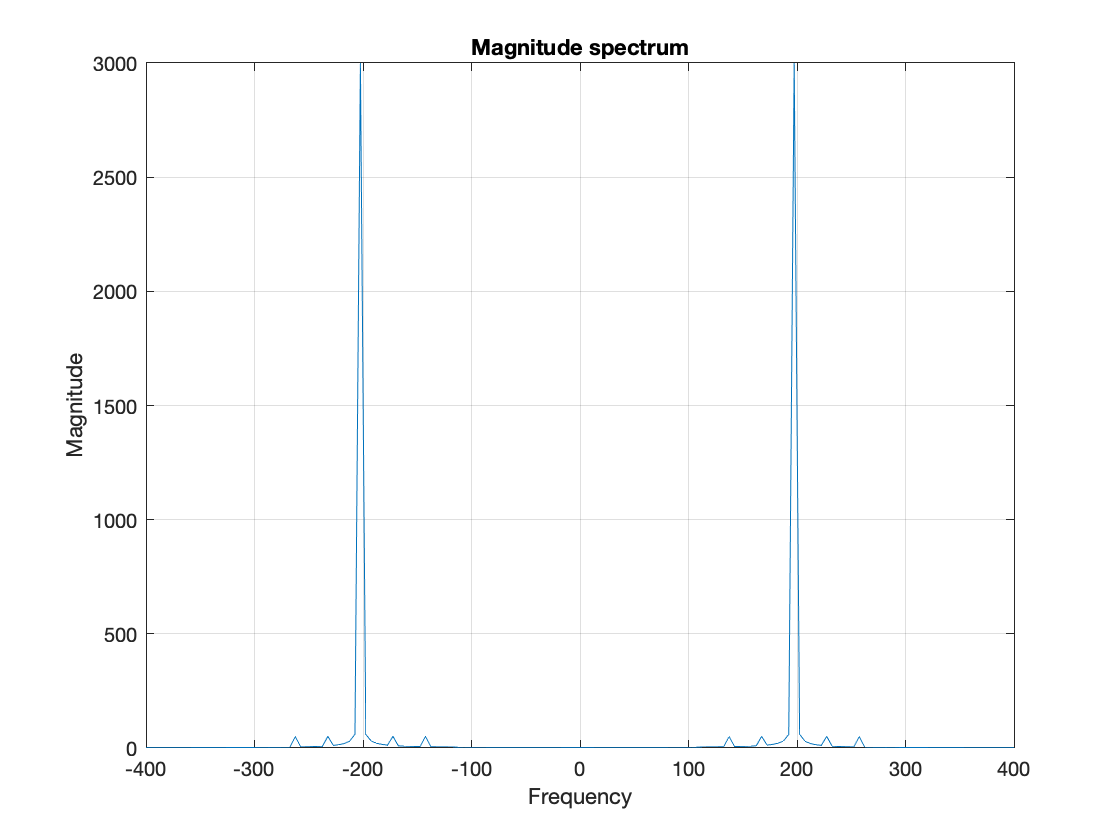

%Plotting magnitude spectrum(Modulated Signal)-

plot(fshift, freq); 
title('Magnitude spectrum'); 
xlim([-2*fc,2*fc]);
xlabel('Frequency'); 
ylabel('Magnitude'); 
grid on;

#### Demodulation of modulated signal- 

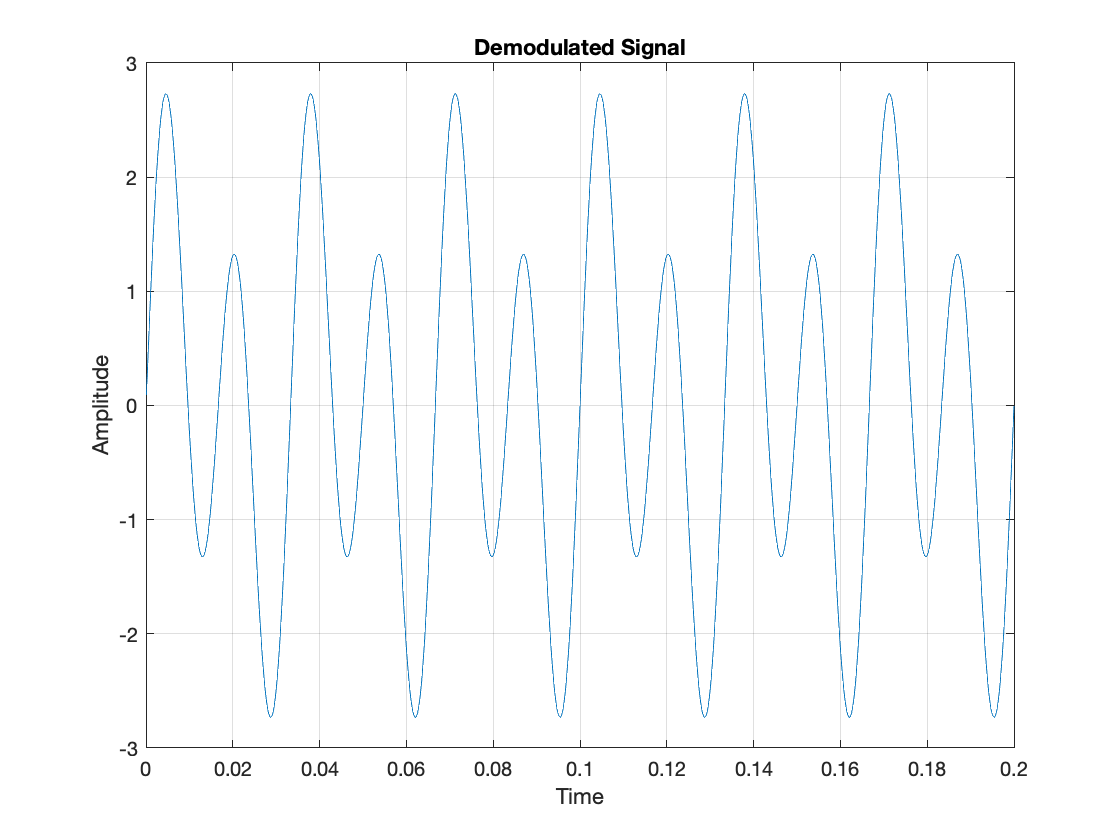

dif_mod = diff(mod_fm)*fs; %taking differentiation of modulated signal
env = envelope(dif_mod);   %finding envelope of differentiated signal
env1 = env - mean(env);    %Removing DC value from envelope
demod = env1/(2*pi*Ac*kf);

%As diff() removes first element from array so redefining time axis
t2 = [1/fs:1/fs:0.2];   

%Taking Fourier Transform of modulated signal-
n = length(demod);
Y = fft(demod);
Fam = fftshift(Y);
fshift = (-n/2:n/2-1)*(fs/n); % zero-centered frequency range
freq = abs(Fam);   

%Plotting Demodulated signal-

plot(t2, demod); 
title('Demodulated Signal'); 
xlabel('Time'); 
ylabel('Amplitude'); 
grid on;

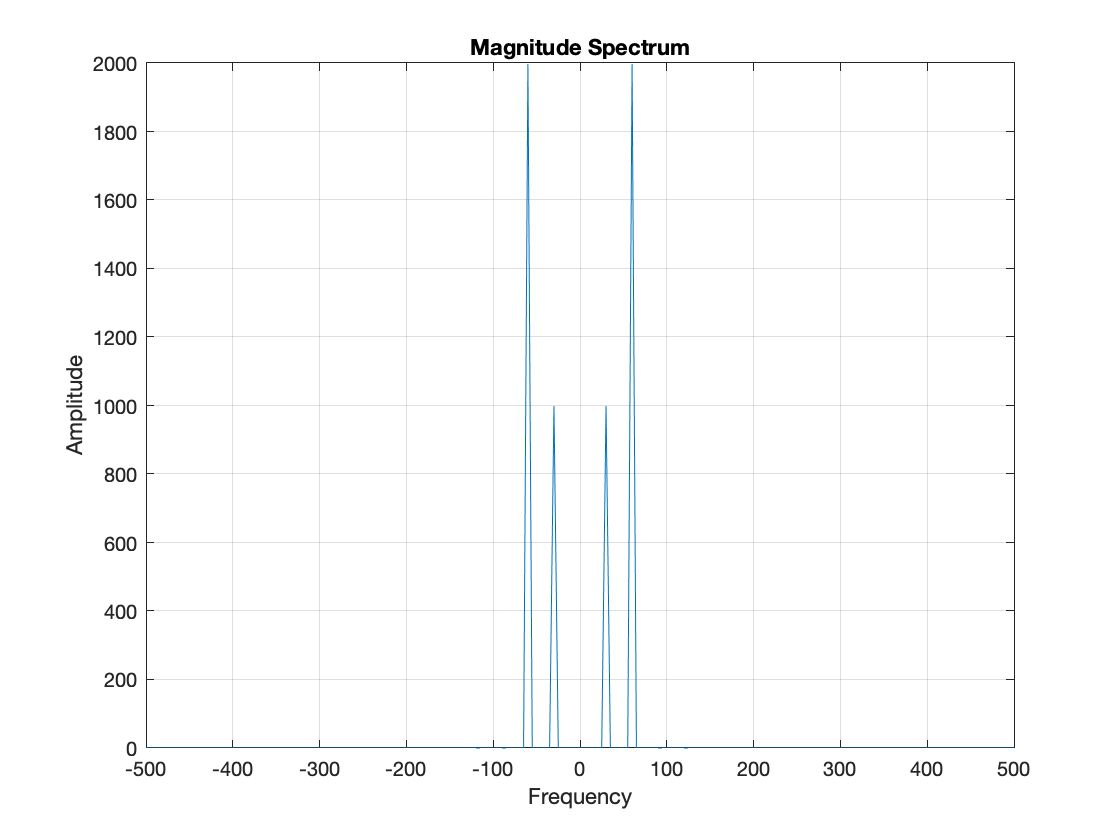

%Plotting magnitude spectrum of Demodulated signal-

plot(fshift, freq); 
title('Magnitude Spectrum'); 
xlim([-2.5*fc,2.5*fc]);
xlabel('Frequency'); 
ylabel('Amplitude'); 
grid on;

#### THE END